# MBSE with the F-16A: linking requirements to the model and to tests

You have written requirements. Today you will see what happens when they are **linked**: to the functions that implement them, to the parts that realize them, and to the tests that check them. The example is a teaching model of the F-16A built in four layers, **RFLP** (Requirements, Functions, Logical, Physical), with System Composer and Requirements Toolbox.

Run the sections in order with **Run Section** (Ctrl+Enter). Nothing in this script changes the model files.

## 0 · Setup

Two questions that a requirements document cannot answer quickly: *Where is* `REQ_F16A_011` *(Mach 1.6 at 36,000 ft) satisfied?* and *Why does the F100 engine exist?* By the end of the hour the model will answer both.

This section finds the example and starts from a clean slate, with no project and no requirement set in memory.

lectures = fileparts(which("F16A_MBSE_Class"));
assert(~isempty(lectures), "Make the mbse/lectures folder your current folder, then run this section again.")
f16aDir = fullfile(fileparts(lectures), "examples", "f16a");
if ~isempty(matlab.project.rootProject)
    close(matlab.project.rootProject)   % closing a project also closes its models
end
slreq.clear                             % unload every requirement set and link set
f16aDir

f16aDir = "C:\Users\darsh\Documents\GitHub\air-vehicle-design\air_vehicle_design\mbse\examples\f16a"

## 1 · A tour of the example

Before linking anything, look at what gets linked. The example models the F-16A because the answer is known: the real aircraft has one F100 engine, so you can check whether the method reaches it. Its 26 requirements come from the Brandt F-16A reference sizing spreadsheet, the same kind of sizing model you use for your RFP.

The example is a **MATLAB project**, `f16a.prj`, with one folder per layer:

**Words you will meet.** Most are System Composer or Requirements Toolbox terms. The ones marked *this example* are the author's own.

Open the project. Its **Project** panel lists the folders above, so browse them while the next sections open one artifact from each layer. Look, but don't edit: if you move a block by accident, don't save it. Notice the `~mdl.slmx` and `~m.slmx` files beside the models and tests. They matter in section 4.

proj = openProject(fullfile(f16aDir, "f16a.prj"));

### 1.1 · R: the requirements

The requirements are a Requirements Toolbox set, not a document: each one is an object with an ID, a summary, a description and a rationale. This opens the set in the **Requirements Editor** (double-clicking `requirements/f16a.slreqx` in the Project panel does the same) and lists the 26 requirements by category.

rs = slreq.open(fullfile(f16aDir, "requirements", "f16a.slreqx"));
items = rs.find(Type="Requirement");
reqs = items(arrayfun(@(r) isempty(r.children), items));     % drop the category headings
category = erase(arrayfun(@(r) string(r.parent.Summary), reqs(:)), " requirements");
allRequirements = table(category, string({reqs.Id}).', string({reqs.Summary}).', ...
    VariableNames=["Category", "Id", "Summary"])

allRequirements = 26×3 table
         Category                Id                           Summary                  
    ___________________    ______________    __________________________________________

    "Mission profile"      "REQ_F16A_001"    "Takeoff condition"                       
    "Mission profile"      "REQ_F16A_002"    "Acceleration condition"                  
    "Mission profile"      "REQ_F16A_003"    "Climb condition"                         
    "Mission profile"      "REQ_F16A_004"    "Outbound cruise condition"               
    "Mission profile"      "REQ_F16A_005"    "Dash condition"                          
    "Mission profile"      "REQ_F16A_006"    "Combat condition"                        
    "Mission profile"      "REQ_F16A_007"    "Egress condition"                        
    "Mission profile"      "REQ_F16A_008"    "Return cruise condition"      

Two of these come back all hour. Read them in full:

for id = ["REQ_F16A_011" "REQ_F16A_022"]
    r = rs.find(Type="Requirement", Id=id);
    disp(id + ": " + r.Summary + newline + newline + r.Description + newline + newline + ...
        "Rationale: " + r.Rationale + newline + " ")
end

REQ_F16A_011: Max-Mach point performance

The aircraft shall be capable of sustained level flight (Ps = 0, Main!X3, input) at Mach 1.6 (Main!U3, input). This applies at these conditions: weight fraction W/W_TO = 0.8997 (Main!S3, computed elsewhere from fuel-state cells), altitude 36,000 ft (Main!T3, input), load factor n = 1 (Main!V3, input) and 100% afterburner (Main!W3, input).

Rationale: Defines the top-speed design point on the T/W-vs-W/S constraint diagram (Consts row 23).
 
REQ_F16A_022: Composite material fraction limit

The structural material mix of the airframe shall use composite materials (carbon fiber and fiberglass) for no more than 20% of the structural weight. The values are carbon fiber = 20% (Cost!B42, input) and fiberglass = 0% (Cost!B43, input). The remainder shall be Aluminum 65% (Cost!B41, input), Steel 5% (Cost!B44, input) and Titanium 10% (Cost!B45, input). All five fractions are direct Excel inputs, and their sum is 100% (Cost!B46, formula check).

Rationale: 

Each description names the spreadsheet cells it came from, and each rationale says why the requirement exists.

**Try it** in the Requirements Editor:

- Expand *Point performance requirements* and select `REQ_F16A_011`. The fields on the right match what was printed above.

- Further down on the right, the **Links** section shows what `REQ_F16A_011` is linked to: two elements of `F16A_Functional`, the next stop. Where those links are stored is the question in section 3.

- Look at `REQ_F16A_023` and `REQ_F16A_024`. They are deliberately blank, a student exercise explained in `docs/01_requirements.md`.

### 1.2 · F: the functions

Of the two requirements in section 1.1, `REQ_F16A_011` is a **performance** requirement, a flight condition the aircraft must reach, so functions implement it. `REQ_F16A_022` is a **constraint**, a limit on what the airframe may be made of. It is a property of a part, so a physical component implements it.

`F16A_Functional` is a System Composer architecture whose components are **functions**, what the aircraft must do, with no hint of how. Here is its tree:

fm = systemcomposer.openModel("F16A_Functional");
functionTree = sort(extractAfter(string(find(fm, systemcomposer.query.AnyComponent, Recurse=true)), "F16A_Functional/"))

functionTree = 9×1 string array
    "ProvideAircraftFunctions"
    "ProvideAircraftFunctions/Aviate"
    "ProvideAircraftFunctions/Aviate/GenerateLift"
    "ProvideAircraftFunctions/Aviate/MaintainStructuralIntegrity"
    "ProvideAircraftFunctions/Aviate/ManageFuel"
    "ProvideAircraftFunctions/Aviate/Maneuver"
    "ProvideAircraftFunctions/Aviate/ProduceThrust"
    "ProvideAircraftFunctions/Communicate"
    "ProvideAircraftFunctions/Navigate"


In the diagram, double-click `ProvideAircraftFunctions`, then `Aviate`, to find `GenerateLift` and `ProduceThrust`. These are the two elements `REQ_F16A_011` is linked to. Function names are verbs. They say what must happen, not what makes it happen: *produce thrust*, not *engine*.

The `functions/` folder holds a second F artifact, `F16A_MissionActivity.slx`. It is an activity diagram that flies the ten mission phases in order, and it opens in section 4.

### 1.3 · L: the logical roles

`F16A_Logical` names the **roles** that carry out the functions, still without naming a product. A name after a slash, like `PropulsionSystem/SingleEngine`, is one of the competing **kinds** that role could be:

lm = systemcomposer.openModel("F16A_Logical");
roles = sort(extractAfter(string(find(lm, systemcomposer.query.AnyComponent, Recurse=true)), "F16A_Logical/"))

roles = 15×1 string array
    "Airframe"
    "Airframe/BlendedCrankedDelta"
    "Airframe/ConventionalTrapWing"
    "AvionicsSuite"
    "CommunicationSystem"
    "FlightControlSystem"
    "FlightControlSystem/FlyByWire"
    "FlightControlSystem/HydroMechanical"
    "FuelSystem"
    "LandingGear"
    "MissionSystemsBay"
    "PropulsionSystem"
    "PropulsionSystem/SingleEngine"
    "PropulsionSystem/TwinEngine"
    "WeaponSystem"


Find `PropulsionSystem` in the diagram and look inside it. It is a **variant**: it holds two kinds, `SingleEngine` and `TwinEngine`, and L does not choose between them. Section 5 explains why.

### 1.4 · P: the physical parts

`F16A_Physical` holds real parts, and where a choice is still open, real **candidates**. Unlike roles, candidates carry numbers. Here are the three engines in `Aircraft/Propulsion/Engine`:

pm = systemcomposer.openModel("F16A_Physical");
cands = getChoices(lookup(pm, Path="F16A_Physical/Aircraft/Propulsion/Engine")).';
value = @(name) arrayfun(@(c) getEvaluatedPropertyValue(c, "F16A_PhysicalProps.EngineCandidate." + name), cands);
engines = table(value("Thrust_SL_lb"), value("Mass_lb"), value("TRL"), string(value("DataProvenance")), ...
    RowNames=string({cands.Name}), VariableNames=["Thrust_SL_lb", "Mass_lb", "TRL", "Source"])

engines = 3×4 table
                                 Thrust_SL_lb    Mass_lb    TRL      Source   
                                 ____________    _______    ___    ___________

    F100_PW_200                     23770        4730.2      8     "Reference"
    LowThrustSingle_Surrogate       18500          5100      4     "Estimate" 
    TwinEngine_Surrogate            32000          6400      6     "Estimate" 

	Get insights using Copilot


Only the F100's numbers are `Reference` data, from the real engine. The other two candidates are `Estimate`s, made up to give the trade something to choose between. The numbers are stored on the components themselves: select `F100_PW_200` in the diagram and open the **Property Inspector** to see them. Section 7 scores these three engines; the next section explains where those fields come from.

### 1.5 · Stereotypes and properties: data the modeler adds

A System Composer component starts with a name and very little else: no mass, no thrust, no TRL. The engine table exists because the author of this example **built** three kinds of thing, and none of them ships with System Composer:

- A **profile** is a file of custom definitions that a model imports. `physical/F16A_PhysicalProps.xml` serves `F16A_Physical`, and `logical/F16A_LogicalOptions.xml` serves `F16A_Logical`.

- A **stereotype** is a custom type of component, defined in a profile. `EngineCandidate` and `PhysicalItem` are two of them.

- A **property** is a data field that a stereotype declares, with a type and a default value. `Thrust_SL_lb` is one. Apply a stereotype to a component, and the component gets the stereotype's fields to fill in with its own values.

If you know MATLAB classes: a stereotype is like a class definition, its properties are like the class's properties, and applying it to a component is like creating an object that holds its own values.

Here is every stereotype in the two profiles:

stereotypes = table(strings(0,1), strings(0,1), strings(0,1), VariableNames=["Profile", "Stereotype", "DeclaredProperties"]);
for prof = [lm.Profiles, pm.Profiles]
    for s = prof.Stereotypes
        stereotypes(end+1, :) = {prof.Name, s.Name, strjoin(string({s.Properties.Name}), ", ")}; %#ok<AGROW>
    end
end
stereotypes

stereotypes = 9×3 table
           Profile                  Stereotype                                                           DeclaredProperties                                                
    _____________________    ________________________    __________________________________________________________________________________________________________________

    "F16A_LogicalOptions"    "SolutionOption"            "Selected, DecisionRef"                                                                                           
    "F16A_PhysicalProps"     "AirframeCandidate"         "Mass_lb, AeroBenefit, TRL, DataProvenance, Selected"                                                             
    "F16A_PhysicalProps"     "EngineCandidate"           "Mass_lb, Thrust_SL_lb, TRL, DataProvenance, Selected"                                                            
    "F16A_Phy

A component can carry several stereotypes. `F100_PW_200` carries three: what kind of thing it is (`EngineCandidate`), what every part records (`PhysicalItem`), and why it is in the model (`Rationale`).

f100 = lookup(pm, Path="F16A_Physical/Aircraft/Propulsion/Engine/F100_PW_200");
appliedToF100 = string(f100.getStereotypes).'

appliedToF100 = 3×1 string array
    "F16A_PhysicalProps.EngineCandidate"
    "F16A_PhysicalProps.PhysicalItem"
    "F16A_PhysicalProps.Rationale"


systemcomposer.profile.editor("F16A_PhysicalProps")

The **Profile Editor** has opened. In its Profile Browser, expand `F16A_PhysicalProps` and select `EngineCandidate` to see its properties and their types and defaults. Then go back to the `F16A_Physical` diagram and select `F100_PW_200`: the Property Inspector groups its values by stereotype.

Keep one more word apart. System Composer also has **parameters**, a built-in feature for values on a component, often ones that a Simulink behavior model uses. This model doesn't use parameters. When the documentation says *parameter*, it does not mean these properties.

### 1.6 · Tests: the verification tests

A verification test is an ordinary MATLAB unit test. The `verification/` folder holds three of them, and this opens the first one you will use, `F16AMaterialsVerificationTest`, in the Editor.

verificationTests = string({dir(fullfile(f16aDir, "verification", "*Test.m")).name}).'

verificationTests = 3×1 string array
    "F16AFuelVerificationTest.m"
    "F16AMaterialsVerificationTest.m"
    "F16AStaticMarginVerificationTest.m"


edit(fullfile(f16aDir, "verification", "F16AMaterialsVerificationTest.m"))

Read `testAirframeCompositeWithinLimit`. The line `verifyLessThanOrEqual(cf, 0.20, ...)` is `REQ_F16A_022` written as code. `cf` is the airframe's composite fraction, which `F16APhysicalMaterialsRollup` adds up from the parts in `F16A_Physical`.

Notice what the test file does *not* contain: anything that ties it to the requirement. `REQ_F16A_022` appears only in comments and messages. The link is stored separately, in `F16AMaterialsVerificationTest~m.slmx`, next to the test.

## 2 · The map: four layers, three kinds of link

You have now seen one artifact from every layer. Each layer is its own file. **Links** tie the layers together, and there are only three kinds:

One rule explains most of what follows: **a link is stored with the artifact it starts from**, not with the requirement.

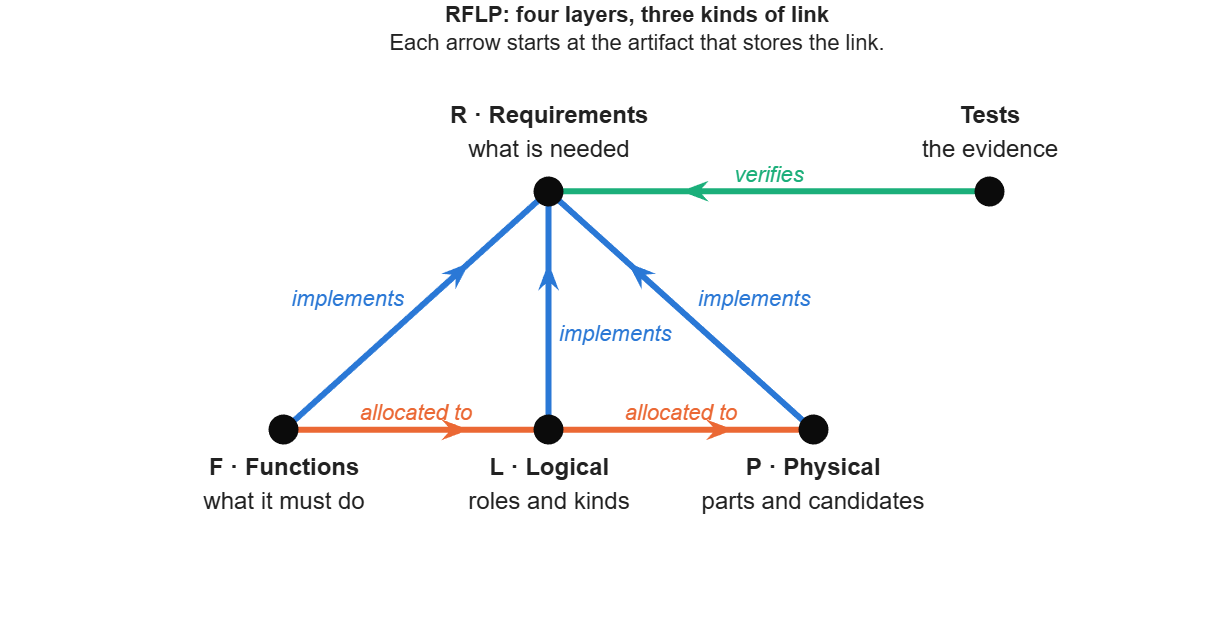

blue = "#2a78d6"; orange = "#eb6834"; aqua = "#1baf7a";
G = digraph(["F" "L" "P" "F" "L" "T"], ["R" "R" "R" "L" "P" "R"]);
pos = dictionary(["R" "F" "L" "P" "T"], {[2.5 2], [1 1], [2.5 1], [4 1], [5 2]});
xy = cell2mat(pos(string(G.Nodes.Name)));
isImplement = G.Edges.EndNodes(:,2) == "R" & G.Edges.EndNodes(:,1) ~= "T";
isAllocate  = G.Edges.EndNodes(:,2) ~= "R";
edgeInk = repmat(hex2rgb(aqua), numedges(G), 1);
edgeInk(isImplement,:) = repmat(hex2rgb(blue), nnz(isImplement), 1);
edgeInk(isAllocate,:)  = repmat(hex2rgb(orange), nnz(isAllocate), 1);
plot(G, XData=xy(:,1), YData=xy(:,2), NodeLabel={}, MarkerSize=14, NodeColor="#0b0b0b", ...
    EdgeColor=edgeInk, EdgeAlpha=1, LineWidth=3, ArrowSize=14, ArrowPosition=0.7);
theme(gcf, "light"); set(gcf, Position=[0 0 820 420])
layerLabel = @(x, y, s, va) text(x, y, s, FontSize=12, HorizontalAlignment="center", VerticalAlignment=va);
layerLabel(2.5, 2.1, ["\bfR · Requirements"; "\rmwhat is needed"], "bottom");
layerLabel(5.0, 2.1, ["\bfTests"; "\rmthe evidence"], "bottom");
layerLabel(1.0, 0.9, ["\bfF · Functions"; "\rmwhat it must do"], "top");
layerLabel(2.5, 0.9, ["\bfL · Logical"; "\rmroles and kinds"], "top");
layerLabel(4.0, 0.9, ["\bfP · Physical"; "\rmparts and candidates"], "top");
linkLabel = @(x, y, s, c, ha) text(x, y, s, Color=c, FontSize=11, FontAngle="italic", HorizontalAlignment=ha);
linkLabel(1.68, 1.55, "implements", blue, "right");
linkLabel(2.56, 1.40, "implements", blue, "left");
linkLabel(3.35, 1.55, "implements", blue, "left");
linkLabel(1.75, 1.07, "allocated to", orange, "center");
linkLabel(3.25, 1.07, "allocated to", orange, "center");
linkLabel(3.75, 2.07, "verifies", aqua, "center");
axis off; xlim([0.3 5.7]); ylim([0.45 2.55])
title("RFLP: four layers, three kinds of link", "Each arrow starts at the artifact that stores the link.")

## 3 · A requirement set on its own

In the tour, the Requirements Editor listed links. Now close everything, load **only** the requirement set, and ask it how many of its 26 requirements are implemented.

if ~isempty(matlab.project.rootProject)
    close(matlab.project.rootProject)   % closes the models you opened in the tour
end
slreq.clear                             % unload every requirement set and link set
rs = slreq.load(fullfile(f16aDir, "requirements", "f16a.slreqx"));
rs.updateImplementationStatus;
before = rs.getImplementationStatus

before = struct with fields:
    implemented: 0
      justified: 0
           none: 26
          total: 26


## 4 · Load the models, and the links come with them

Open the project, then load every model, requirement set and test link set. `F16AOpenForReview` also opens the **Requirements Editor** and the mission activity diagram.

openProject(fullfile(f16aDir, "f16a.prj"));
F16AOpenForReview

Loaded 3 architectures, the mission activity, 4 requirement sets and 3 verification link set(s).
Verified by a test: REQ_F16A_022, REQ_F16A_025, REQ_F16A_P01.


rs.updateImplementationStatus;
after = rs.getImplementationStatus

after = struct with fields:
    implemented: 26
      justified: 0
           none: 0
          total: 26


The links were in the model files all along. `functions/F16A_Functional~mdl.slmx` sits next to `F16A_Functional.slx`, so loading the model loaded its links. (With the project open, Requirements Toolbox also loads the project's link sets for you.)

**Try it** in the Requirements Editor:

- Turn on the **Implementation Status** column. Every requirement now shows that something implements it.

- Select `REQ_F16A_009` (Loiter). The **Links** section on the right says it is *implemented by* `Loiter`, an action in the mission activity diagram. Click the link to jump there.

- Open `f16a_functional_derived`. `D01` to `D09` were *discovered* by decomposing the functions, and the original requirements never mention them. Functional analysis feeds back into R, and their acceptance criteria are still `TBD`.

## 5 · Functions are allocated to logical roles

F says *what* the aircraft must do. L says *how*, in **roles**: `Airframe`, `PropulsionSystem`, `FlightControlSystem` and six more. An **allocation** says which role realizes which function. Allocations live in their own files, allocation sets, so you can review them as a matrix.

systemcomposer.openModel("F16A_Logical");
systemcomposer.allocation.editor

Three roles are **variants**. Each holds two competing **kinds**, and L deliberately does not pick one:

Why can't L choose? A role has no mass, cost or maturity. Only a real part does, and scoring kinds here would mean inventing those numbers.

**The name test.** Swap the technology underneath: does the name still make sense? If it does, the box belongs at L. If it names a product, a supplier or a number, it belongs at P.

## 6 · Ask the model: where is REQ_F16A_011 satisfied?

Every layer is linked, so a short query can walk from a requirement all the way down to the parts. `traceRequirement` (at the bottom of this script) follows the Implement links, then the F→L and L→P allocations, and checks which options are active.

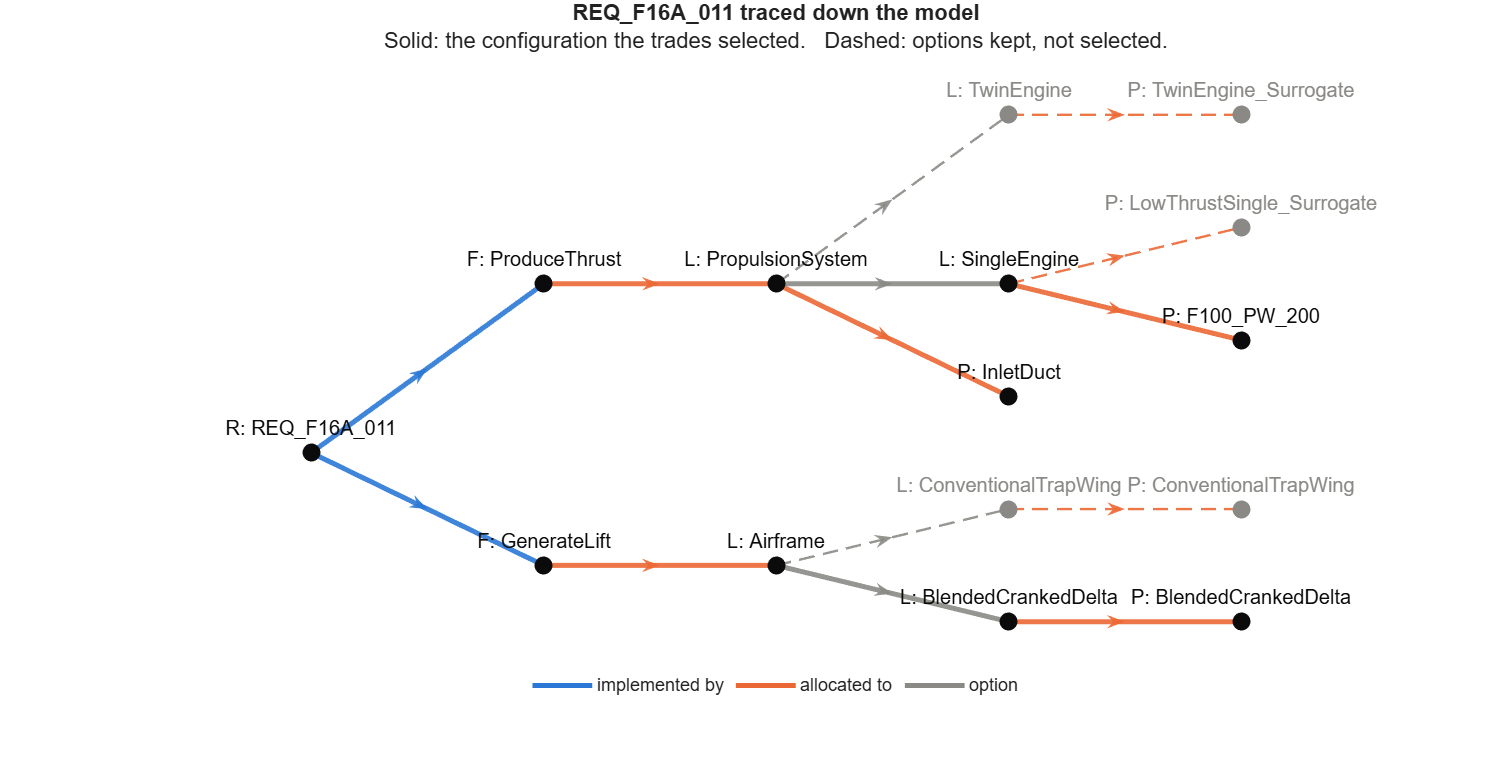

reqId = "REQ_F16A_011";                        % the requirement to trace
E = traceRequirement(reqId);
plotTrace(E, reqId)

Read it from left to right. `REQ_F16A_011` is implemented by two functions. Each function is allocated to a role, each role offers two kinds, and each kind is allocated to the physical candidates that could realize it. Now answer the opening question, *why does the F100 exist?*, by following the solid line backwards.

## 7 · The trade study: P decides

P is where real candidates carry real numbers, so P is where a kind gets chosen. The engine trade scores the three engine candidates on thrust, mass and maturity (TRL), as a weighted sum of declared value functions:


$$ \textrm{score} = \sum_k w_k \, v_k(x_k) $$


`ref` is the F100, the one candidate whose numbers come from the reference data.

ranked = F16AEngineTradeStudy(Record=false);   % Record=false: score and rank, write nothing


  ENGINE TRADE STUDY
  Question: which engine should the F-16A use?
  Answer recorded in: REQ_F16A_L01

[STEP 1] OPEN THE MODEL
  F16A_Physical, variant F16A_Physical/Aircraft/Propulsion/Engine

[STEP 2] READ THE CANDIDATES (stereotype EngineCandidate)
  found F100_PW_200                kind SingleEngine  Thrust_SL_lb=23770  Mass_lb=4730.23  TRL=8  (Reference)
  found LowThrustSingle_Surrogate  kind SingleEngine  Thrust_SL_lb=18500  Mass_lb=5100  TRL=4  (Estimate)
  found TwinEngine_Surrogate       kind TwinEngine    Thrust_SL_lb=32000  Mass_lb=6400  TRL=6  (Estimate)
  baseline: F100_PW_200, the only candidate with the tag DataProvenance = Reference

[STEP 3] SCORE THE CANDIDATES
  Thrust_SL_lb  weight 0.30   v = T/T_baseline   (more thrust is better)
  Mass_lb       weight 0.35   v = M_baseline/M   (less mass is better)
  TRL           weight 0.35   v = (TRL-1)/8    


[STEP 4] SELECT THE WINNER
             Candidate                  Kind         Thrust_SL_lb    Mass_lb    TRL    v_Thrust_SL_lb    v_Mass_lb    v_TRL     Score     Baseline    Rank
    ___________________________    ______________    ____________    _______    ___    ______________    _________    _____    _______    ________    ____

    "F100_PW_200"                  "SingleEngine"       23770        4730.2      8              1              1      0.875    0.95625     true        1  
    "TwinEngine_Surrogate"         "TwinEngine"         32000          6400      6         1.3462         0.7391      0.625     0.88

## 8 · What each criterion contributed

Split each score into what each criterion contributed, weight × value. The check confirms these are the weights the trade used.

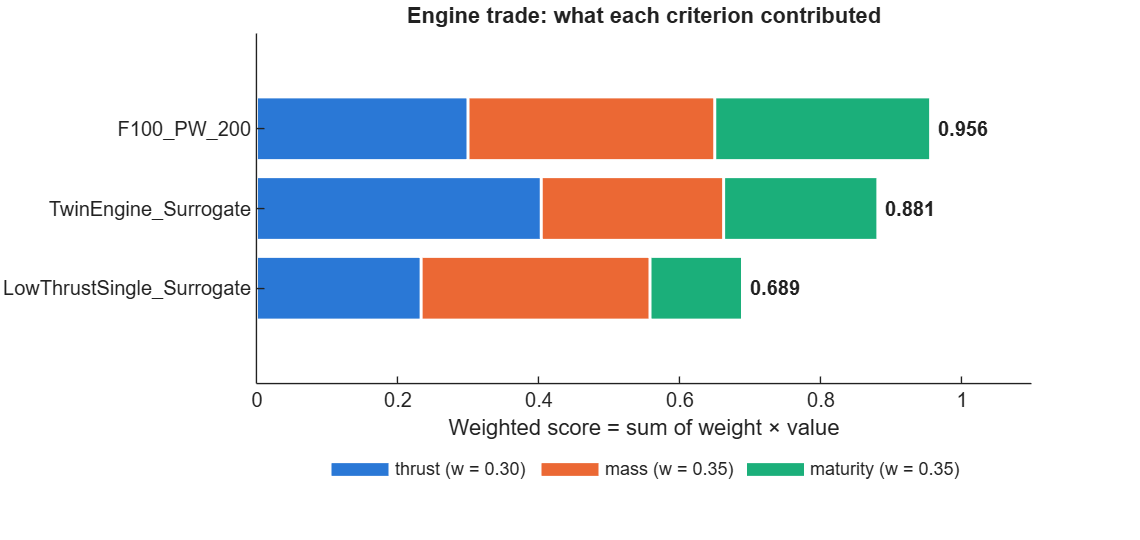

w = [0.30 0.35 0.35];                          % the weights in F16AEngineTradeStudy.m
V = ranked{:, ["v_Thrust_SL_lb", "v_Mass_lb", "v_TRL"]};
contribution = V .* w;
assert(max(abs(sum(contribution, 2) - ranked.Score)) < 1e-12, "w is not what the trade used.")
b = barh(contribution, "stacked", EdgeColor="w", LineWidth=1.5);
theme(gcf, "light"); set(gcf, Position=[0 0 760 360])
[b.FaceColor] = deal(blue, orange, aqua);
set(gca, YDir="reverse", YTickLabel=ranked.Candidate, TickLabelInterpreter="none", Box="off")
text(ranked.Score + 0.01, 1:height(ranked), compose("%.3f", ranked.Score), FontWeight="bold")
legend(compose("thrust (w = %.2f)", w(1)), compose("mass (w = %.2f)", w(2)), ...
    compose("maturity (w = %.2f)", w(3)), Location="southoutside", Orientation="horizontal", Box="off")
xlim([0 1.1]); xlabel("Weighted score = sum of weight × value")
title("Engine trade: what each criterion contributed")

The twin gains 0.104 on thrust, then loses 0.091 on mass and 0.088 on maturity. Installed mass and maturity outweigh a large thrust advantage. Look at the twin's thrust value, 1.35: a ratio has no ceiling, so its thrust counts for more than the 0.30 weight suggests. That is why the trade printed a warning.

## 9 · Move a weight

A weighted sum is only as objective as its weights, and the author chose these. Change `wThrust` and run this section again. Mass and maturity share the rest equally.

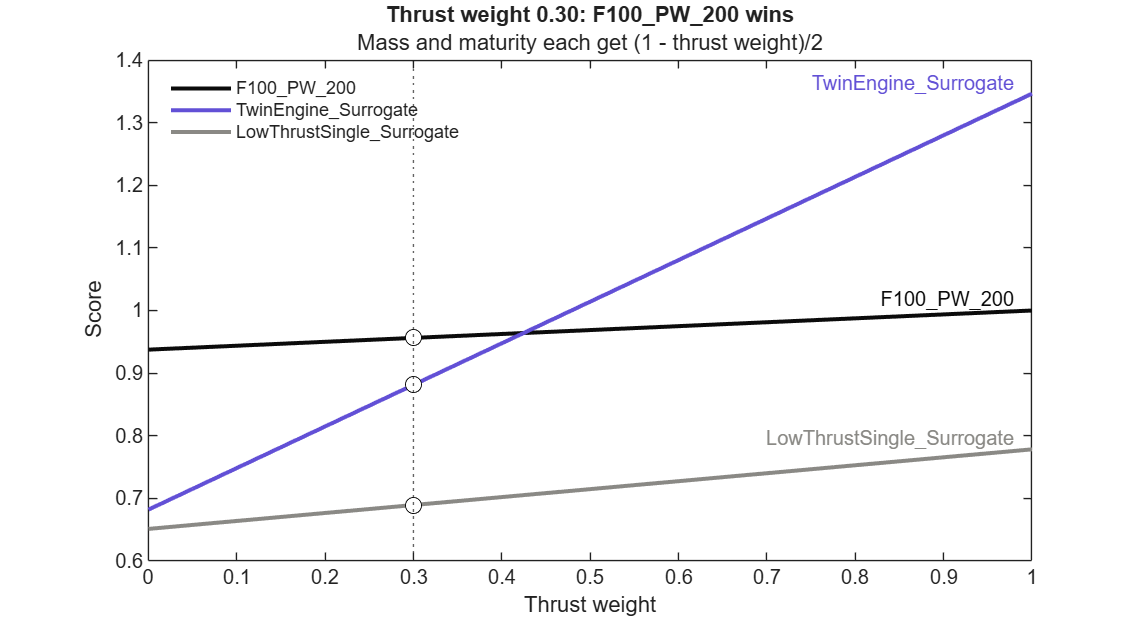

wThrust = 0.30;                                % try 0.35, 0.40, 0.45, ...
weightsFor = @(t) [t, (1 - t)/2, (1 - t)/2];
score = V * weightsFor(wThrust).';
[~, best] = max(score);
sweep = linspace(0, 1, 201).';
S = [sweep, (1 - sweep)/2, (1 - sweep)/2] * V.';
curves = plot(sweep, S, LineWidth=2);            % plot first: this section gets its own figure
theme(gcf, "light"); set(gcf, Position=[0 0 760 420])
lineInk = ["#0b0b0b", "#6250d6", "#8a8985"];     % one color per candidate, fixed
hold on
for i = 1:height(ranked)
    set(curves(i), Color=lineInk(i), DisplayName=ranked.Candidate(i));
    text(0.98, S(end,i), ranked.Candidate(i), Color=lineInk(i), Interpreter="none", ...
        HorizontalAlignment="right", VerticalAlignment="bottom");
end
xline(wThrust, ":", HandleVisibility="off");
plot(repmat(wThrust, size(score)), score, "o", MarkerSize=8, Color="#0b0b0b", ...
    MarkerFaceColor="w", HandleVisibility="off");
hold off
legend(Location="northwest", Interpreter="none", Box="off")
xlabel("Thrust weight"); ylabel("Score")
title(compose("Thrust weight %.2f: %s wins", wThrust, ranked.Candidate(best)), ...
    "Mass and maturity each get (1 - thrust weight)/2", Interpreter="none")

A trade that can be flipped by a modest change of weight needs a better argument than its score.

## 10 · What the trade wrote back into the model

Run with `Record=true` (the default), the trade records its decision in all three layers. It already has, so here you read the result back instead of running it again. The decision is spread over two models and a requirement set, so `plotDecision` (at the bottom of this script) reads all three and draws them in one picture:

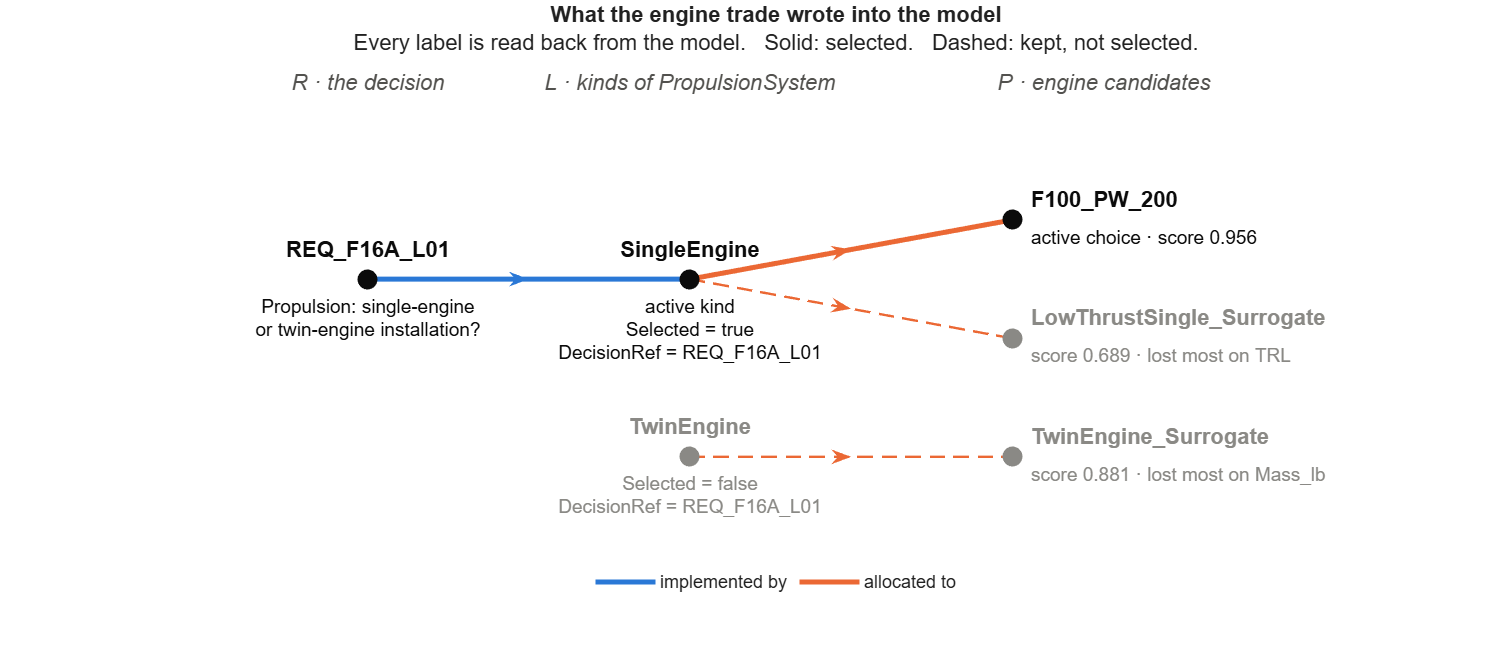

plotDecision()

Read the figure from right to left, the order in which the trade wrote it:

- **P:** the winner, `F100_PW_200`, became the active choice of the `Engine` variant. Every candidate got a `Selected` value and a `Rationale` property, which is where each score and "lost most on" in the figure comes from.

- The trade followed the winner's allocation back to its kind, `SingleEngine`.

- **L:** `SingleEngine` became the active kind of `PropulsionSystem`, with `Selected = true`. Both kinds got `DecisionRef = REQ_F16A_L01`.

- **R:** an Implement link from `SingleEngine` to `REQ_F16A_L01`, the requirement that posed the question.

Losing candidates are never deleted, because their `Rationale` is the only record of why they lost. Here is the twin's in full:

pm = systemcomposer.loadModel("F16A_Physical");
twin = lookup(pm, Path="F16A_Physical/Aircraft/Propulsion/Engine/TwinEngine_Surrogate");
justification = string(getProperty(twin, "F16A_PhysicalProps.Rationale.Justification"));
whyNot = strip(extractBefore(justification, " ||"), "'")   % stereotype strings are stored quoted

whyNot = "Trade study: NOT SELECTED (rank 2 of 3). Score 0.88130, against 0.95625 for the selected F100_PW_200. Deficit -0.07495 (this candidate minus the winner) = Thrust_SL_lb (+0.10387), Mass_lb (-0.09132), TRL (-0.08750). Criterion with the largest loss: Mass_lb. Criteria (D-015): Thrust_SL_lb T/T_baseline w=0.30, Mass_lb M_baseline/M w=0.35, TRL (TRL-1)/8 w=0.35. Ratio baseline: F100_PW_200. Kept as the traded alternative (D-002). Decision recorded in REQ_F16A_L01."

Requirements Toolbox can show the R side of all three trades at once. This **Traceability Matrix** sets the logical decision requirements against the logical model. Each marked cell is an Implement link that a trade wrote:

decisions.leftArtifacts = {char(fullfile(f16aDir, "requirements", "f16a_logical_derived.slreqx"))};
decisions.topArtifacts  = {char(fullfile(f16aDir, "logical", "F16A_Logical.slx"))};
slreq.generateTraceabilityMatrix(decisions)

The engine trade linked `REQ_F16A_L01` to `SingleEngine`, the flight-controls trade linked `L02` to `FlyByWire`, and the airframe trade linked `L03` to `BlendedCrankedDelta`. A blank column, like `TwinEngine`, is an option that was kept but not chosen.

## 11 · The code behind the numbers

Links and stereotypes describe the design, but they calculate nothing. The numbers that the tests check come from ordinary MATLAB functions. Each one reads properties from the model, does the engineering calculation, and returns a number:

After a design change, `F16ARunAnalyses` runs all of them in the correct order. It writes each result onto `Aircraft` as a **Measure of Merit**, a number that grades the design (a property of the `MeasureOfMerit` stereotype in section 1.5), and then saves the models. This class must not change the models, so here you run the analyses one at a time, and they write nothing. Here are the four numbered steps of `F16ARunAnalyses.m`:

showCode(fullfile(f16aDir, "F16ARunAnalyses.m"), "% 1) Make the decisions.", "save_system(")

% 1) Make the decisions.
trades = {F16AEngineTradeStudy(), F16AAirframeTradeStudy(), F16AFlightControlsTradeStudy()};

pm       = systemcomposer.loadModel("F16A_Physical");
aircraft = lookup(pm, Path="F16A_Physical/Aircraft");
% The constants of the cost model describe the reference engine. If the trade
% selected a different engine, stop here, before a Measure of Merit is written.
F16APhysicalCostModel(pm, PreconditionOnly=true);

% 2) Roll up the configuration that the trades selected.
mass = F16APhysicalMassRollup();          % writes OEW_lb and saves
mats = F16APhysicalMaterialsRollup();
fuel = F16APhysicalFuelRollup();

% 3) Fly the mission.
mission = F16AMissionAnalysis();
setMoM(aircraft, "MissionFuel_lb",  mission.TotalFuel_lb);
setMoM(aircraft, "MissionTime_min", mission.TotalTime_min);
am = systemcomposer.loadActivity("F16A_MissionActivity");
for k = 1:height(mission.Table)
    phase = am.Activity.getNode(char(mission.Table.Phase(k)));
    % The behaviour of Combat is the kil

### 11.1 · Mission analysis: how much fuel the mission burns

`F16AMissionAnalysis` flies the ten phases of the mission activity and adds up their fuel. It prints each step, so you can check the sum by hand.

mission = F16AMissionAnalysis();


  MISSION FUEL ANALYSIS
  Question: how much fuel does the design mission burn?
  Supports: REQ_F16A_001-010 (the 'required' side of REQ_F16A_P01)

[STEP 1] LIST THE TEN PHASES THAT THE MODEL FLIES
  These are the actions of F16A_MissionActivity, in flow order:
  Takeoff -> Accel -> Climb -> Cruise -> Dash -> Combat -> Egress -> Cruise2 -> Loiter -> Landing

[STEP 2] RUN THE /sizing/ MISSION ANALYSIS
  Analysis  : sizing/VnV/BrandtF16A/BrandtMission.m
  Segments  : 14
  Flown at  : 31377 lb take-off gross weight (Wt!B3)

[STEP 3] CHECK THAT THE FOUR OMITTED SEGMENTS USE NO FUEL OR TIME
  Patrol ............... omitted: 0.0 lb, 0.0 min
  Patrol2 .............. omitted: 0.0 lb, 0.0 min
  Patrol3 .............. omitted: 0.0 lb, 0.0 min
  Climb2 ............... omitted: 0.0 lb, 0.0 min

  -> All 4 use no fuel or time. Thus the ten phases fly the same mission as the 14 segm

Where does each number come from? Each phase in `F16A_MissionActivity` is an action, and each action stores a MATLAB call as its **behavior**, not a number:

am = systemcomposer.loadActivity("F16A_MissionActivity");
behavior = arrayfun(@(p) string(am.Activity.getNode(char(p)).BehaviorDefinition), mission.Table.Phase);
behavior(behavior == "") = "child activity: the kill chain";
phases = addvars(mission.Table(:, ["Phase", "Fuel_lb", "Time_min"]), behavior, After="Phase", NewVariableNames="Behavior");
phases.Fuel_lb = round(phases.Fuel_lb);           % whole pounds and tenths of a minute are enough to read
phases.Time_min = round(phases.Time_min, 1)

phases = 10×4 table
      Phase                  Behavior                Fuel_lb    Time_min
    _________    ________________________________    _______    ________

    "Takeoff"    "F16AMissionSegment('Takeoff')"      1540         0.2  
    "Accel"      "F16AMissionSegment('Accel')"         376         2.2  
    "Climb"      "F16AMissionSegment('Climb')"         444         4.5  
    "Cruise"     "F16AMissionSegment('Cruise')"        994          23  
    "Dash"       "F16AMissionSegment('Dash')"          479           6  
    "Combat"     "child activity: the kill chain"      565           2  
    "Egress"     "F16AMissionSegment('Egress')"        301           6  
    "Cruise2"    "F16AMissionSegment('Cruise2')"       777        30.1  
    "Loiter"     "F16AMissionSegment('Loiter')"        484          20  
    "Landing"    "F16AMissionSegment('La

`F16AMissionSegment` calculates nothing either. It looks the phase up in the result of the sizing mission analysis, `sizing/VnV/BrandtF16A/BrandtMission.m`, which reproduces the *Miss* tab of Brandt's F-16A spreadsheet. Here is the end of `segment_generic_`, the function that most phases use:

sizingDir = fullfile(fileparts(fileparts(lectures)), "sizing", "VnV", "BrandtF16A");
showCode(fullfile(sizingDir, "BrandtMission.m"), "% Part 1: drag fuel", "dW = part1 + part2 + part3;")

% Part 1: drag fuel
part1 = cT / 60 * q_avg * dc * t;

% Part 2: climb/acceleration energy fuel
%   Δh × 2/(V_s+V_e) = time-averaged climb rate factor [s]
%   ΔV / g            = velocity change factor [s]
% Energy term is ONLY added for climbs/accelerations (energy_s > 0).
% Descents are NOT credited — matches Miss tab (e.g. N13 Loiter
% descends 30,000 ft but has no energy term in the Excel formula).
dh = alt_end - alt_start;
dV = V_end - V_start;
energy_s = dh * 2 / (V_start + V_end) + dV / g;  % [s]
if energy_s > 0
    part2 = cT / 3600 * W_frac * energy_s;
else
    part2 = 0;
end

% Part 3: dropped payload
part3 = drop / W_TO;

dW = part1 + part2 + part3;


*Part 1* is the fuel equation you already know, divided by the takeoff weight: fuel burned = thrust-specific fuel consumption × drag × time. (In steady flight, thrust equals drag.) `dc` is the drag coefficient sum, computed a few lines above. Parts 2 and 3 add the fuel to climb or speed up, and the weight of any stores released.


$$ W_{\textrm{fuel}} = c_T \, D \, t $$


`F16ARunAnalyses` wrote the mission total onto `Aircraft`. Compare that value with the total that you just calculated:

aircraft = lookup(pm, Path="F16A_Physical/Aircraft");
recorded = @(name) getEvaluatedPropertyValue(aircraft, "F16A_PhysicalProps.MeasureOfMerit." + name);
missionFuel = table(round(mission.TotalFuel_lb), round(recorded("MissionFuel_lb")), ...
    VariableNames=["Calculated_lb", "RecordedInModel_lb"])

missionFuel = 1×2 table
    Calculated_lb    RecordedInModel_lb
    _____________    __________________

        5960                5960       

	Get insights using Copilot


### 11.2 · Mass roll-up: from parts to empty weight

The operating empty weight (OEW) is the sum of `Mass_lb` over the parts. There is a trap: `F16A_Physical` holds **every** candidate, the losers too. So a roll-up first builds an **analysis instance**, a copy of the architecture that keeps only the active choice of each variant, together with each part's property values. Then it adds the masses, parts before assemblies. `rollUpMass`, at the bottom of this script, is the whole algorithm in about ten lines.

inst = instantiate(pm.Architecture, "F16A_PhysicalProps", "ClassRollup");
oew = table(round(rollUpMass(lookup(inst, "Path", "F16A_Physical/Aircraft"))), round(recorded("OEW_lb")), ...
    VariableNames=["Calculated_lb", "RecordedInModel_lb"])

oew = 1×2 table
    Calculated_lb    RecordedInModel_lb
    _____________    __________________

        19981              19981       

	Get insights using Copilot


The two agree. Now list what the instance left out:

massProp = "F16A_PhysicalProps.PhysicalItem.Mass_lb";
leftOut = table(strings(0,1), strings(0,1), zeros(0,1), VariableNames=["Variant", "Candidate", "Mass_lb"]);
for v = ["Airframe", "FlightControls", "Propulsion/Engine"]
    role = lookup(pm, Path="F16A_Physical/Aircraft/" + v);
    for c = getChoices(role)
        if c ~= getActiveChoice(role)
            leftOut(end+1, :) = {role.Name, c.Name, getEvaluatedPropertyValue(c, massProp)}; %#ok<AGROW>
        end
    end
end
leftOut

leftOut = 4×3 table
        Variant                  Candidate             Mass_lb
    ________________    ___________________________    _______

    "Airframe"          "ConventionalTrapWing"          7300  
    "FlightControls"    "HydroMechanical"                700  
    "Engine"            "LowThrustSingle_Surrogate"     5100  
    "Engine"            "TwinEngine_Surrogate"          6400  

	Get insights using Copilot


withTheLosers_lb = round(oew.Calculated_lb + sum(leftOut.Mass_lb))

withTheLosers_lb = 39481

Count the losers too, and the aircraft has two airframes, two flight-control systems and three engines, at about twice its empty weight. For this reason `F16ARunAnalyses` runs the roll-ups **after** the trade studies: the trades choose the configuration, and then the roll-ups measure it.

`F16APhysicalMassRollup` does the same calculation and prints every subtotal. To see it, type `F16APhysicalMassRollup(Persist=false)` in the Command Window. With `Persist=false`, it writes nothing.

### 11.3 · Two analyses, one requirement

`REQ_F16A_P01` says that the tanks shall hold at least the fuel that the mission burns. One side of that comparison comes from the parts, and the other from the mission. The fuel roll-up finds the tanks by asking each part under `FuelSystem` whether it has the `FuelTank` stereotype, so it would count a fourth tank without a change to its code.

available_lb = F16APhysicalFuelRollup().AvailableFuel_lb;


  AVAILABLE FUEL ROLL-UP
  Question: how much fuel can this aeroplane carry?
  Supports: REQ_F16A_P01 (the 'available' side)

[STEP 1] OPEN THE MODEL
  Model     : F16A_Physical
  Start at  : F16A_Physical/Aircraft/FuelSystem
  Property  : F16A_PhysicalProps.FuelTank.FuelCapacity_lb

[STEP 2] FIND THE PARTS THAT HOLD FUEL
  Question to each part below FuelSystem: do you have a FuelTank stereotype?

    FuelSystem               no FuelTank stereotype. Looking inside its 3 part(s)
      AftFuselageTank          YES. Holds 2100 lb of fuel
      FwdFuselageTank          YES. Holds 2100 lb of fuel
      WingTank                 YES. Holds 2100 lb of fuel

  -> 3 part(s) answered yes.

[STEP 3] ADD THE CAPACITIES
  AftFuselageTank ...... +    2100  =     2100 lb
  FwdFuselageTank ...... +    2100  =     4200 lb
  WingTank ............. +    2100  =     6300 lb

[STEP 4] REPO

margin_lb = round(available_lb - mission.TotalFuel_lb)

margin_lb = 340

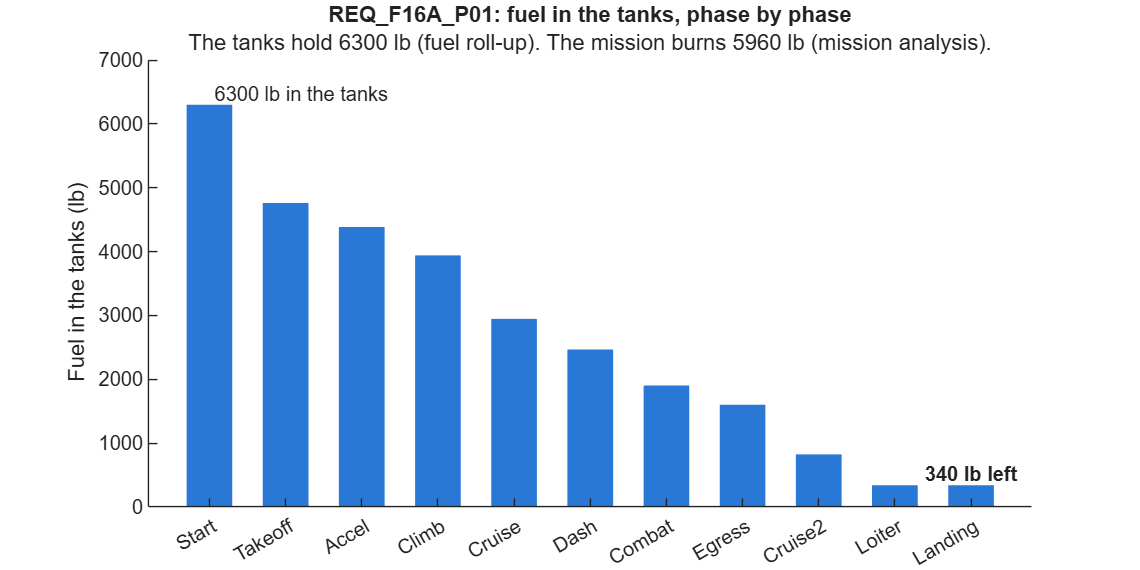

inTanks_lb = available_lb - [0; cumsum(mission.Table.Fuel_lb)];
stage = categorical(["Start"; mission.Table.Phase], ["Start"; mission.Table.Phase]);
bar(stage, inTanks_lb, 0.6, FaceColor=blue, EdgeColor="none");
theme(gcf, "light"); set(gcf, Position=[0 0 760 380])
text(1, inTanks_lb(1), compose(" %.0f lb in the tanks", inTanks_lb(1)), VerticalAlignment="bottom")
text(numel(inTanks_lb), inTanks_lb(end), compose("%.0f lb left", inTanks_lb(end)), ...
    VerticalAlignment="bottom", HorizontalAlignment="center", FontWeight="bold")
ylim([0 7000]); ylabel("Fuel in the tanks (lb)"); box off
title("REQ_F16A_P01: fuel in the tanks, phase by phase", ...
    compose("The tanks hold %.0f lb (fuel roll-up). The mission burns %.0f lb (mission analysis).", ...
    available_lb, mission.TotalFuel_lb), Interpreter="none")

`F16AFuelVerificationTest` makes this same comparison with `verifyGreaterThanOrEqual(available, required, msg)`, and section 12 runs it from the requirement. It reads the required side from `MissionFuel_lb` in the model, the value that you compared in section 11.1.

## 12 · Verification: link a requirement to a test

A **Verify** link joins a requirement to the test that checks it. Three requirements in this model have one:

Run the tests **from the requirement sets**, so each result is recorded against its requirement:

physical = slreq.find(Type="ReqSet", Name="f16a_physical_derived");
evalc("runTests(rs); runTests(physical);");    % evalc hides the roll-ups' printed walk-throughs
rs.updateVerificationStatus; physical.updateVerificationStatus;
ids = ["REQ_F16A_022"; "REQ_F16A_P01"; "REQ_F16A_025"];
verdict = strings(size(ids));
for k = 1:numel(ids)
    s = slreq.find(Type="Requirement", Id=ids(k)).getVerificationStatus;
    if s.failed > 0,     verdict(k) = "VIOLATED: a linked test failed";
    elseif s.passed > 0, verdict(k) = "met: every linked test passed";
    else,                verdict(k) = "not evaluated";
    end
end
table(ids, verdict, VariableNames=["Requirement", "Verdict"])

ans = 3×2 table
     Requirement                  Verdict             
    ______________    ________________________________

    "REQ_F16A_022"    "met: every linked test passed" 
    "REQ_F16A_P01"    "met: every linked test passed" 
    "REQ_F16A_025"    "VIOLATED: a linked test failed"

	Get insights using Copilot


In the Requirements Editor, turn on the **Verification Status** column. You should see two green requirements and one red.

## 13 · Why REQ_F16A_025 is red, and why red is correct

Run the static-margin test on its own and read its message.

runtests("F16AStaticMarginVerificationTest")

Running F16AStaticMarginVerificationTest
..
Verification failed in F16AStaticMarginVerificationTest/testLandingStaticMarginIsNegative.
    ----------------
    Test Diagnostic:
    ----------------
    REQ_F16A_025 NOT MET at landing (landing weight. run() builds it internally from the sizing point W_TO = 31377 lb: it sets the expendable payload and all three fuel thirds to zero. W_land = W_empty + perm_payload, approximately 20,678 lb computed): static margin +0.2065 %MAC is NOT BELOW the 0 %MAC upper bound. At this end of the CG range, the aircraft is MORE STABLE than REQ_F16A_025 allows. That bound is strict. A margin exactly equal to it does not satisfy the requirement, because neutral stability is not relaxed stability. A margin at or above zero is conventional stability. That is not the relaxed configuration that justified the fly-by-wire selection of REQ_F16A_L02. The margin printed

ans =   1×3 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   2 Passed, 1 Failed (rerun), 0 Incomplete.
   0.76755 seconds testing time.


At landing, with fuel burned and stores released, the CG has moved forward of the neutral point. The margin is positive (stable), so the requirement $ \textrm{SM} < 0 $ is violated. The test that passes, `testAnalysisProducedUsableMargins`, proves the analysis ran, so the red is a **verdict**, not a broken tool. The violation is a property of the simplified reference model, not of the real F-16A.

A requirement can be in one of three states: **not evaluated**, **met** or **violated**. A Verify link records *that* a requirement is checked, and by what, not that it passed.

## 14 · Take it to your design

When a test is red, three responses are legitimate: change the design, change the requirement with a recorded justification, or show that the analysis is wrong. Never edit a test to make it go green.

The same pattern fits your RFP:

- **R:** your point-performance and mission requirements, which you already have.

- **F:** what the aircraft must do. Link each function to the requirements it implements.

- **L:** roles, plus your concept options as kinds: single or twin engine, tube-and-wing or blended body, conventional tail or canard.

- **P:** real candidates with numbers. Trade them with value functions declared in advance, and record why the losers lost.

- **Analyses:** write your mass roll-up and mission fuel calculation as functions that read the model's properties, and run them after every trade. Then a change to one part reaches every number.

- **Verify:** write one test per hard constraint, link it to the requirement, and let it go red when the design fails.

**Homework** (more in `examples/f16a/docs/README.md`):

- Write acceptance criteria for two of `D01`–`D09`. No external source defines them, so you must argue for your numbers.

- Repeat section 9 for the airframe trade (`F16AAirframeTradeStudy(Record=false)`). How far can its weights move before the winner changes?

- In the Property Inspector, add 500 to the `Mass_lb` of `Wing` in `F16A_Physical`, but don't save. Run section 11.2 again. Which other numbers in the table at the top of section 11 would change, if you ran `F16ARunAnalyses`? Close the model without saving.

- Add a fourth engine candidate to `F16A_Physical`, allocate it from a kind, and run `F16AEngineTradeStudy(Record=false)`. What happens if you skip the allocation?

## Helper functions

function E = traceRequirement(reqId)
%TRACEREQUIREMENT Every edge below one requirement, read from the model's links and allocations.
E = emptyTrace();
rNode = "R: " + reqId;
links = slreq.find(Type="Requirement", Id=reqId).inLinks();
for k = 1:numel(links)
    src = links(k).source();
    if string(links(k).Type) == "Verify"                    % a test checks it
        [~, test] = fileparts(src.artifact);
        E(end+1,:) = {rNode, "Test: " + test, "verified by", true}; %#ok<AGROW>
        continue
    end
    elem = slreq.structToObj(src);                          % the element that implements it
    if ~isa(elem, "systemcomposer.arch.BaseComponent")      % a mission-phase action
        E(end+1,:) = {rNode, "F: " + elem.Name, "implemented by", true}; %#ok<AGROW>
        continue
    end
    switch extractBefore(string(elem.getQualifiedName), "/")
        case "F16A_Functional"
            E(end+1,:) = {rNode, "F: " + elem.Name, "implemented by", true}; %#ok<AGROW>
            roles = systemcomposer.allocation.load("F16A_FunctionToLogical").Scenarios(1).getAllocatedTo(elem);
            for j = 1:numel(roles)
                E(end+1,:) = {"F: " + elem.Name, "L: " + roles(j).Name, "allocated to", true}; %#ok<AGROW>
                E = [E; traceRole(roles(j))]; %#ok<AGROW>
            end
        case "F16A_Logical"
            E(end+1,:) = {rNode, "L: " + elem.Name, "implemented by", true}; %#ok<AGROW>
            E = [E; traceRole(elem)]; %#ok<AGROW>
        otherwise
            E(end+1,:) = {rNode, "P: " + elem.Name, "implemented by", true}; %#ok<AGROW>
    end
end
E = unique(E, "stable");                                    % two functions can share a role
end
function E = traceRole(role)
%TRACEROLE A logical role's parts, its kinds, and the candidates each kind is allocated to.
lp = systemcomposer.allocation.load("F16A_LogicalToPhysical").Scenarios(1);
E = emptyTrace();
parts = lp.getAllocatedTo(role);
for j = 1:numel(parts)
    E(end+1,:) = {"L: " + role.Name, "P: " + parts(j).Name, "allocated to", true}; %#ok<AGROW>
end
if ~isa(role, "systemcomposer.arch.VariantComponent"), return, end
kinds = getChoices(role);
activeKind = string(getActiveChoice(role).Name);
for j = 1:numel(kinds)
    kindActive = string(kinds(j).Name) == activeKind;
    E(end+1,:) = {"L: " + role.Name, "L: " + kinds(j).Name, "option", kindActive}; %#ok<AGROW>
    cands = lp.getAllocatedTo(kinds(j));
    for i = 1:numel(cands)
        variant = cands(i).Parent.Parent;                   % the P variant that holds it
        candActive = string(getActiveChoice(variant).Name) == string(cands(i).Name);
        E(end+1,:) = {"L: " + kinds(j).Name, "P: " + cands(i).Name, "allocated to", ...
            kindActive && candActive}; %#ok<AGROW>
    end
end
end
function E = emptyTrace()
E = table(strings(0,1), strings(0,1), strings(0,1), false(0,1), ...
    VariableNames=["From", "To", "Relation", "Active"]);
end
function plotTrace(E, reqId)
%PLOTTRACE Draw a trace: color = kind of link, solid = the configuration the trades selected.
relations = ["implemented by", "allocated to", "option", "verified by"];
colors    = ["#2a78d6", "#eb6834", "#8a8985", "#1baf7a"];
G = digraph(E.From, E.To, E(:, ["Relation", "Active"]));
[~, r] = ismember(G.Edges.Relation, relations);
onPath = ismember(G.Nodes.Name, ["R: " + reqId; G.Edges.EndNodes(G.Edges.Active, 2)]);
ink = repmat(hex2rgb("#0b0b0b"), numnodes(G), 1);
ink(~onPath,:) = repmat(hex2rgb("#8a8985"), nnz(~onPath), 1);
h = plot(G, Layout="layered", Direction="right", EdgeColor=hex2rgb(colors(r)), EdgeAlpha=0.9, ...
    LineWidth=2.5, ArrowSize=9, MarkerSize=8, NodeColor=ink, NodeLabel={}, HandleVisibility="off");
theme(gcf, "light"); set(gcf, Position=[0 0 1000 520])
off = G.Edges.EndNodes(~G.Edges.Active, :);
highlight(h, off(:,1), off(:,2), LineStyle="--", LineWidth=1.2);
for n = 1:numnodes(G)                                       % labels above the nodes, clear of the edges
    text(h.XData(n), h.YData(n) + 0.12, G.Nodes.Name{n}, Color=ink(n,:), FontSize=10, ...
        HorizontalAlignment="center", VerticalAlignment="bottom", Interpreter="none");
end
hold on
for k = unique(r).'                                         % one legend entry per kind of link shown
    plot(NaN, NaN, Color=colors(k), LineWidth=2.5, DisplayName=relations(k));
end
hold off
legend(Location="southoutside", Orientation="horizontal", Box="off")
xlim([min(h.XData) - 0.5, max(h.XData) + 0.5]); ylim([min(h.YData) - 0.3, max(h.YData) + 0.5])
axis off
title(reqId + " traced down the model", ...
    "Solid: the configuration the trades selected.   Dashed: options kept, not selected.", ...
    Interpreter="none")
end
function plotDecision()
%PLOTDECISION What the engine trade wrote into R, L and P, read back from the model.
pm = systemcomposer.loadModel("F16A_Physical");
lm = systemcomposer.loadModel("F16A_Logical");
lp = systemcomposer.allocation.load("F16A_LogicalToPhysical").Scenarios(1);
engine = lookup(pm, Path="F16A_Physical/Aircraft/Propulsion/Engine");
role   = lookup(lm, Path="F16A_Logical/PropulsionSystem");
decision = slreq.find(Type="Requirement", Id="REQ_F16A_L01");
% Nodes: R at x = 0, L kinds at x = 1.4, P candidates at x = 2.8.
name = "R: " + string(decision.Id); x = 0; y = NaN;
detail = {splitlines(regexprep(string(decision.Summary), "(.{20,}?)\s", "$1\n", "once"))};
from = strings(0,1); to = strings(0,1); relation = strings(0,1); active = false(0,1);
kinds = getChoices(role);
activeKind = string(getActiveChoice(role).Name);
activeCand = string(getActiveChoice(engine).Name);
row = 0;
for k = 1:numel(kinds)
    kindNode = "L: " + kinds(k).Name;
    isKind = string(kinds(k).Name) == activeKind;
    cands = lp.getAllocatedTo(kinds(k));
    ys = zeros(1, numel(cands));
    for i = 1:numel(cands)
        row = row + 1; ys(i) = -row;
        why = string(getProperty(cands(i), "F16A_PhysicalProps.Rationale.Justification"));
        % The trade's verdict reads "Score 0.88130 ... Criterion with the largest loss: Mass_lb."
        score = str2double(regexp(why, "(?i)score (\d+\.\d+)", "tokens", "once"));
        if string(cands(i).Name) == activeCand
            note = compose("active choice · score %.3f", score);
        else
            lostOn = regexp(why, "(?:largest loss:|lost most on) (\w+)", "tokens", "once");
            note = compose("score %.3f · lost most on %s", score, string(lostOn));
        end
        name(end+1) = "P: " + cands(i).Name; x(end+1) = 2.8; y(end+1) = ys(i); %#ok<AGROW>
        detail{end+1} = note; %#ok<AGROW>
        from(end+1) = kindNode; to(end+1) = name(end); relation(end+1) = "allocated to"; %#ok<AGROW>
        active(end+1) = isKind && string(cands(i).Name) == activeCand; %#ok<AGROW>
    end
    selected = getEvaluatedPropertyValue(kinds(k), "F16A_LogicalOptions.SolutionOption.Selected");
    ref = string(getEvaluatedPropertyValue(kinds(k), "F16A_LogicalOptions.SolutionOption.DecisionRef"));
    note = ["Selected = " + string(selected); "DecisionRef = " + ref];
    if isKind, note = ["active kind"; note]; end
    name(end+1) = kindNode; x(end+1) = 1.4; y(end+1) = mean(ys); detail{end+1} = note; %#ok<AGROW>
end
links = decision.inLinks();
for j = 1:numel(links)
    if string(links(j).Type) ~= "Implement", continue, end
    from(end+1) = name(1); to(end+1) = "L: " + links(j).getSourceLabel; %#ok<AGROW>
    relation(end+1) = "implemented by"; active(end+1) = true; %#ok<AGROW>
end
y(1) = y(name == to(relation == "implemented by"));
% Draw: the same colors and line styles as the trace in section 6.
G = digraph(from, to);
[~, order] = ismember(string(G.Nodes.Name), name);
[~, e] = ismember(join(string(G.Edges.EndNodes), "|", 2), from + "|" + to);
edgeInk = repmat(hex2rgb("#eb6834"), numedges(G), 1);
edgeInk(relation(e) == "implemented by", :) = repmat(hex2rgb("#2a78d6"), nnz(relation(e) == "implemented by"), 1);
onPath = ismember(name(order), [name(1), to(active)]);
nodeInk = repmat(hex2rgb("#8a8985"), numnodes(G), 1);
nodeInk(onPath, :) = repmat(hex2rgb("#0b0b0b"), nnz(onPath), 1);
h = plot(G, XData=x(order), YData=y(order), NodeLabel={}, MarkerSize=9, NodeColor=nodeInk, ...
    EdgeColor=edgeInk, EdgeAlpha=1, LineWidth=2.5, ArrowSize=10, HandleVisibility="off");
theme(gcf, "light"); set(gcf, Position=[0 0 1000 440])
off = G.Edges.EndNodes(~active(e), :);
highlight(h, off(:,1), off(:,2), LineStyle="--", LineWidth=1.2);
for n = 1:numnodes(G)
    k = order(n); right = x(k) == 2.8;
    if right, ha = "left"; dx = 0.08; dyName = 0.06; dyNote = -0.06;
    else, ha = "center"; dx = 0; dyName = 0.14; dyNote = -0.14;
    end
    text(x(k) + dx, y(k) + dyName, extractAfter(name(k), ": "), Color=nodeInk(n,:), FontSize=11, ...
        FontWeight="bold", HorizontalAlignment=ha, VerticalAlignment="bottom", Interpreter="none");
    text(x(k) + dx, y(k) + dyNote, detail{k}, Color=nodeInk(n,:), FontSize=9.5, ...
        HorizontalAlignment=ha, VerticalAlignment="top", Interpreter="none");
end
header = @(xx, s) text(xx, 0.05, s, FontSize=11, FontAngle="italic", Color="#52514e", ...
    HorizontalAlignment="center", VerticalAlignment="bottom", Interpreter="none");
header(0,   "R · the decision");
header(1.4, "L · kinds of PropulsionSystem");
header(3.2, "P · engine candidates");
hold on
plot(NaN, NaN, Color="#2a78d6", LineWidth=2.5, DisplayName="implemented by");
plot(NaN, NaN, Color="#eb6834", LineWidth=2.5, DisplayName="allocated to");
hold off
legend(Location="southoutside", Orientation="horizontal", Box="off")
axis off; xlim([-0.75 4.3]); ylim([min(y) - 0.55, 0.35])
title("What the engine trade wrote into the model", ...
    "Every label is read back from the model.   Solid: selected.   Dashed: kept, not selected.")
end
function showCode(file, fromText, toText)
%SHOWCODE Print the lines of FILE from the line that contains FROMTEXT to the next line that contains TOTEXT.
%   It reads the file and does not open it in the Editor, so nothing can change it by accident.
code  = readlines(file);
first = find(contains(code, fromText), 1);
last  = first - 1 + find(contains(code(first:end), toText), 1);
assert(isscalar(first) && isscalar(last), "Cannot find the lines to show in " + file + ".")
block = code(first:last);
filled = block(strip(block) ~= "");
indent = min(strlength(filled) - strlength(strip(filled, "left")));
disp(strjoin(regexprep(block, "^ {" + indent + "}", ""), newline))
end
function total = rollUpMass(node)
%ROLLUPMASS Add Mass_lb over NODE and everything below it, in an analysis instance.
%   A part gives its own mass. An assembly gives the sum of its parts.
if isempty(node.Components)
    total = node.getValue("F16A_PhysicalProps.PhysicalItem.Mass_lb");
else
    total = 0;
    for child = node.Components
        total = total + rollUpMass(child);
    end
end
end